## MSE 491 DSP - Lab Assignment 1

Authors:

- Abdullah Amjad - 301414558

- Tony Nguyen - 301286979

Created: 26 May 2022

Modified: 01 Jun 2022

clear all
close all
clc

## 1. Creating 'Time' Vector

time = linspace(-1,1,10000);

## 2. Sine Wave Vector

frc1 = 3;
signal1 = sin(2*pi*frc1*time);

## 3. Cos Wave Vector

frc2 = 5;
signal2 = cos(2*pi*frc2*time);

## 4. Sampling frequency (Fs) and Sampling Time(Ts)

Ts = mean(diff(time));
Fs = 1/Ts;

Sampling Frequency =  4999.5 Hz

Sampling Time = 0.2 ms

## 5. Graphing

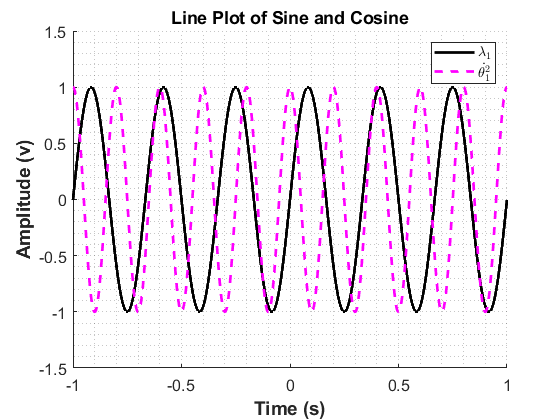

%a. Plot %signal1’ vs ‘time’ in a 2D plot, colour= black, linewidth=2, minor grid.
hold on
plt = plot(time,signal1,'k','LineWidth', 2);
grid minor;
%b. On the same figure, plot %signal2’ vs ‘time’, colour= magenta, linewidth=2, minor grid, style=
%dashed-line
plt2= plot(time, signal2,'--','LineWidth', 2);
plt2.Color = 'magenta';
hold off
%c. Setting the font of axis ticks (not axis label) to size 12
set(gca,'FontSize',12);
%d. Set the x-axis limits to the min and max of the vector %time’
xlim([-1 1]);
%e. Seting the y-axis limits to -1.5 to 1.5 because the largest signal is
%from -1 to 1
ylim([-1.5 1.5]);
%f. Label the x-axis as Time (s), and y-axis as Amplitude (v) with Font size 14, Bold
title('Line Plot of Sine and Cosine');
xlabel('Time (s)','fontweight', 'bold', 'fontsize', 14);
ylabel('Amplitude (v)','fontweight', 'bold', 'fontsize', 14);
%g. Display the legend of the two signals and call signal1 𝜆1 and signal2Θ̇
legend('$$ \lambda_1 $$', '$\dot{\theta_1^2}$', 'Interpreter','latex');
%h. Automatically save the output figure in svg and png formats
saveas(gcf,'Lineplot.png');
saveas(gcf,'Lineplot.svg');

## 6. 3D Circles 

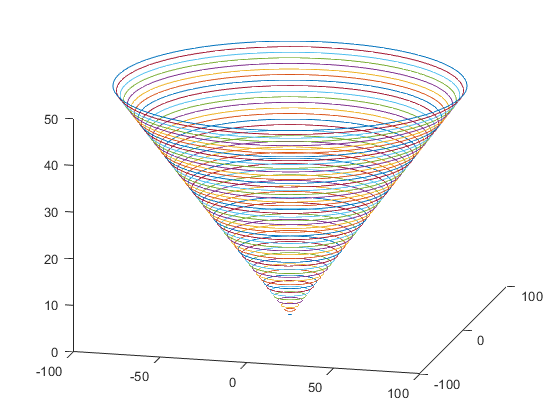

radii = 1:2:100;
height = 1:numel(radii);

figure
%see function at bottom of assignment
circle3D(radii,height);
%show figure in isometric view 
view([14.1 21.2])
saveas(gcf,'circles3D.svg')
saveas(gcf,'circles3D.png')

## 7. Continuous and Discrete Functions

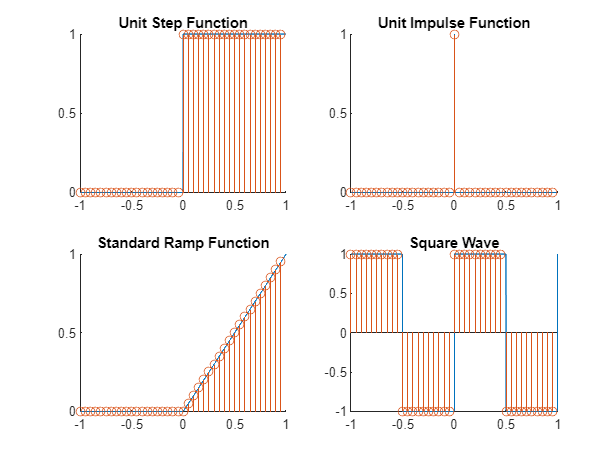

%time interval setup
t_min = -1;
t_max = 1;
t_size = abs(t_min) + abs(t_max);
sample_rate = 1000;
tot_samples=sample_rate*t_size;
t = linspace(t_min,t_max,tot_samples);

ds_factor = 50; %downsampling dactor

%declare functions
unitstep = t>=0;
impulse = t==5.002501250625312e-04; %closest value to zero when downsampled
ramp = t.*unitstep;
sqwave = square(2*pi*t); %frequency ~1 Hz

%plot signals (see function)
figure
subplot(221)
title('Unit Step Function')
plot_signal(t, unitstep, ds_factor)
subplot(222)
title('Unit Impulse Function')
plot_signal(t, impulse, ds_factor)
subplot(223)
title('Standard Ramp Function')
plot_signal(t, ramp, ds_factor)
subplot(224)
title('Square Wave')
plot_signal(t, sqwave, ds_factor)

## 8. Amplitude Modulator

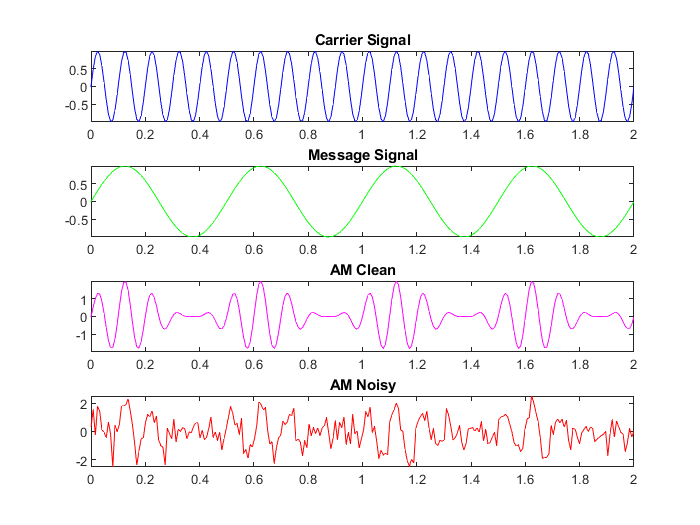

%% To view GUI, click on 'Hide code' to the right
%time interval setup
t_min = 0;
t_max = 2;
t_size = abs(t_min) + abs(t_max);
sample_rate = 125; %lowered from 500 to plot signals faster
tot_samples=sample_rate*t_size;
t = linspace(t_min,t_max,tot_samples);

%Signal properties
fc = 10; %carrier frequency
ac = 1; %carrier amplitude
fm = 2; %message frequency
am = 1; %message amplitude
 

carr = ac*sin(2*pi*fc*t);
msg = am*sin(2*pi*fm*t);
%AM_clean = ammod(msg,fc,sample_rate,0,ac); %Note for TAs: I can explain how 'ammod' works if necessary - Tony
AM_clean = (1 + msg/ac).*carr;
AM_noise = awgn(AM_clean,5); %noise makes AM signal almost unrecognizable, would need to be filtered ot be usable

carr_max = abs(max(abs(carr)));
msg_max = abs(max(abs(msg)));
AM_clean_max = carr_max + msg_max;
AM_noise_max = abs(max(abs(AM_noise)));

figure
for k = 1:length(t)
    if k==length(t)
        break
    end
        
    subplot(411)
    title('Carrier Signal')
    plot(t(k:k+1),carr(k:k+1),'b')
    hold on
    axis([t_min t_max -carr_max carr_max])

    subplot(412)
    title('Message Signal')
    plot(t(k:k+1),msg(k:k+1),'g')
    hold on    
    axis([t_min t_max -msg_max msg_max])

    subplot(413)
    title('AM Clean')
    plot(t(k:k+1),AM_clean(k:k+1),'m')
    hold on
    axis([t_min t_max -AM_clean_max AM_clean_max])

    subplot(414)
    title('AM Noisy')
    plot(t(k:k+1),AM_noise(k:k+1),'r')
    hold on
    axis([t_min t_max -AM_noise_max AM_noise_max])
    
    drawnow
end

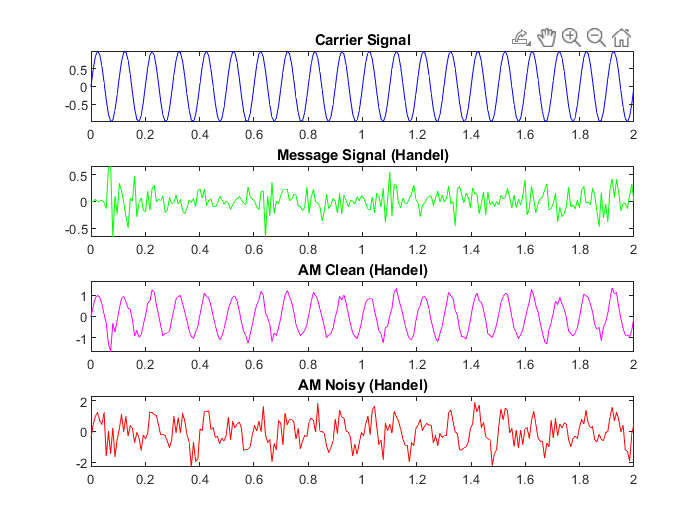

%% Messenger signal as audio sample
%'Hallelujah' by Handel loads sampling frequency (Fs) and audio signal(y)
load handel

carr2 = sin(2*pi*fc*t);
msg2 = interp1(1:length(y), y, linspace(1, length(y), tot_samples));
AM_clean2 = (1 + msg2).*carr2;
AM_noise2 = awgn(AM_clean2,5);

carr_max2 = abs(max(abs(carr2)));
msg_max2 = abs(max(abs(msg2)));
AM_clean_max2 = carr_max2 + msg_max2; %AM mod will not 'work' unless fm << fc 
AM_noise_max2 = abs(max(abs(AM_noise2)));

figure
for k = 1:length(t)
    if k==length(t)
        break
    end
        
    subplot(411)
    title('Carrier Signal')
    plot(t(k:k+1),carr2(k:k+1),'b')
    hold on
    axis([t_min t_max -carr_max2 carr_max2])

    subplot(412)
    title('Message Signal (Handel)')
    plot(t(k:k+1),msg2(k:k+1),'g')
    hold on    
    axis([t_min t_max -msg_max2 msg_max2])

    subplot(413)
    title('AM Clean (Handel)')
    plot(t(k:k+1),AM_clean2(k:k+1),'m')
    hold on
    axis([t_min t_max -AM_clean_max2 AM_clean_max2])

    subplot(414)
    title('AM Noisy (Handel)')
    plot(t(k:k+1),AM_noise2(k:k+1),'r')
    hold on
    axis([t_min t_max -AM_noise_max2 AM_noise_max2])
    
    drawnow
end

## Functions for assignment

function circle3D(r,z)
    hold on
    for i = 1:numel(r)
        th = 0:pi/50:2*pi;
        % x and y coordinates of circle can be modelled after cos and sin
        x = r(i)*cos(th);
        y = r(i)*sin(th);
        h = plot3(x, y, zeros(1,numel(x))+z(i));
    end
    hold off
end

function plot_signal(time,signal,ds_factor)
    %downsample signal
    time_down = downsample(time,ds_factor);
    signal_down = downsample(signal,ds_factor);
    
    %plot continuous and discrete functions
    hold on
    plot(time, signal)
    stem(time_down, signal_down)
    hold off
end